clc, clear
video = VideoReader('RoadTrafficVideo1.mp4');
% implay('videoplayback.mp4')xdxd
pista = read(VideoReader('RoadTrafficVideo1.mp4'), 335);
pista = pista(60:144,:,:);

n = video.NumFrames;
v = video.FrameRate

v = 29.9700

k = fspecial('gaussian', 7, 3);
se = ones(11, 5);
se2 = strel('disk',4, 0);

reporte = zeros(1,n)

reporte =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


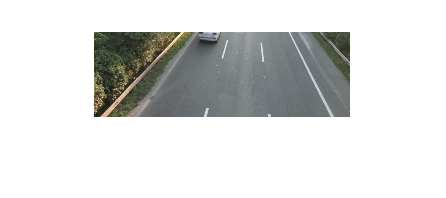


for i = 2:n
    
    autos = read(video, i);
    autos = autos(60:144,:,:);
    I2 = sum(abs(double(autos) - double(pista)), 3);
    mask1 = I2 > 110;
    
    bmf = filter2(k, mask1);
    bm2 = bmf > 0.75;
    
    dil1 = imdilate(bm2, se);
    autos1 = imclose(dil1, se2);
    
    pause(0.05)
    
    L = bwlabel(autos1); 
    
    info = regionprops(autos1, 'Centroid', 'BoundingBox', 'Eccentricity');
    
    n_blobs = max(L(:));
    
    for ind = n_blobs:-1:1 
      if info(ind).Eccentricity > 0.95
        info(ind) = []; 
      end
    end
    
    n_autos = length(info);
    imshow(autos);
    
    contador = 0;
    for ind = 1:n_autos
        if info(ind).BoundingBox (4)>15
            rectangle('Position', info(ind).BoundingBox,'EdgeColor','b', 'LineWidth', 1)
            contador=contador+1;
        end
    end

    reporte(1,i)=contador;
end

plot(reporte)
M = mean(reporte);
carspersecond = M/v;
